%Segunda Parte: Aplicar filtros y transformadas
load_current = syncmachine1(:,1)

load_current =      3
     3
     3
     3
     3
     3
     3
     3
     3
     3


power_factor = syncmachine1(:,2)

power_factor =     0.6600
    0.6800
    0.7000
    0.7200
    0.7400
    0.7600
    0.7800
    0.8000
    0.8200
    0.8400


power_factor_error = syncmachine1(:,3)

power_factor_error =     0.3400
    0.3200
    0.3000
    0.2800
    0.2600
    0.2400
    0.2200
    0.2000
    0.1800
    0.1600


excitation_current_d = syncmachine1(:,4)

excitation_current_d =     0.3830
    0.3720
    0.3600
    0.3380
    0.3170
    0.3010
    0.2900
    0.2800
    0.2500
    0.2210


excitation_current = syncmachine1(:,5)

excitation_current =     1.5630
    1.5520
    1.5400
    1.5180
    1.4970
    1.4810
    1.4700
    1.4600
    1.4300
    1.4010



t = linspace(0,557,557)

t =          0    1.0018    2.0036    3.0054    4.0072    5.0090    6.0108    7.0126    8.0144    9.0162   10.0180   11.0198   12.0216   13.0234   14.0252   15.0270   16.0288   17.0306   18.0324   19.0342   20.0360   21.0378   22.0396   23.0414   24.0432   25.0450   26.0468   27.0486   28.0504   29.0522   30.0540   31.0558   32.0576   33.0594   34.0612   35.0629   36.0647   37.0665   38.0683   39.0701   40.0719   41.0737   42.0755   43.0773   44.0791   45.0809   46.0827   47.0845   48.0863   49.0881



%Transformada rápida de fourier
ft_excitation_current =  fft(excitation_current)

ft_excitation_current = 1.0e+02 *

   8.5258 + 0.0000i
  -0.0301 + 0.2659i
   0.0152 + 0.1392i
   0.0009 + 0.0647i
   0.0015 + 0.0393i
  -0.0633 - 0.0018i
  -0.0986 + 0.0346i
   0.0783 + 0.0568i
   0.0172 - 0.0100i
  -0.0466 - 0.0215i


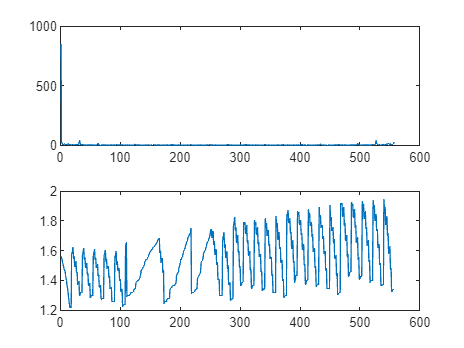

figure()
subplot(2,1,1)
plot(abs(ft_excitation_current))

subplot(2,1,2)
plot(excitation_current)



%Transformada Wavelet
[c,l] = wavedec(excitation_current,4,'db2') %Descomposicion de la señal

c =     6.2407
    6.2702
    5.5521
    5.7669
    5.7377
    5.7090
    5.6908
    5.7021
    5.3148
    5.4272


l =     37
    37
    72
   141
   280
   557


approx = appcoef(c,l,'db2') % Coeficientes de aproximacion

approx =     6.2407
    6.2702
    5.5521
    5.7669
    5.7377
    5.7090
    5.6908
    5.7021
    5.3148
    5.4272


[cd1,cd2,cd3,cd4] = detcoef(c,l,[1,2,3,4]) % Coeficientes de detalle

cd1 =     0.0067
    0.0050
   -0.0025
   -0.0011
    0.0021
   -0.0010
    0.0063
   -0.0100
   -0.0026
    0.1191


cd2 =     0.0028
    0.0103
    0.0175
    0.0073
   -0.0562
    0.1916
   -0.0368
    0.0083
   -0.0283
   -0.1687


cd3 =    -0.0001
    0.0293
   -0.0606
    0.2803
    0.0102
    0.0941
    0.0779
   -0.2716
    0.1228
   -0.3391


cd4 =    -0.0049
    0.0940
    0.4498
    0.3620
    0.2070
   -0.0678
   -0.3823
   -0.2290
   -0.1045
   -0.0021


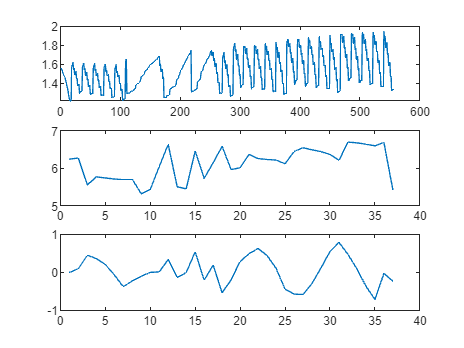


figure()
subplot(3,1,1)
plot(excitation_current)

subplot(3,1,2)
plot(approx)

subplot(3,1,3)
plot(cd4)